Write a MATLAB code for amplitude modulation of DSB-FC

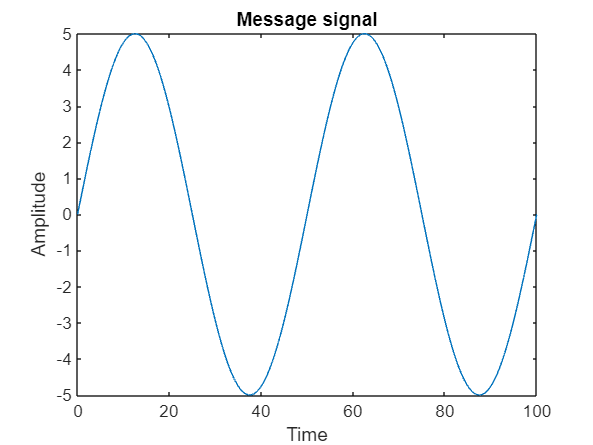

clc;
clear all;
% Generating the message signal
Am = input('Enter the amplitude of the message signal: ');
fm = input('Enter the frequency of the message signal: ');
t = linspace(0,100,5000);
x1 = Am * sin(2*pi*fm*t);
plot(t,x1);
xlabel('Time');
ylabel('Amplitude');
title('Message signal');

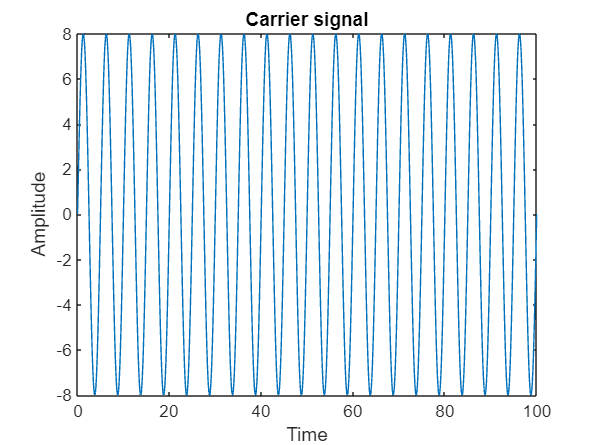

% Generating the carrier signal
Ac = input('Enter the amplitude of the carrier signal: ');
fc = input('Enter the frequency of the carrier signal: ');
c1 = Ac * sin(2*pi*fc*t);
plot(t,c1);
xlabel('Time');
ylabel('Amplitude');
title('Carrier signal');

% Checking the modulation index
m = Am/Ac;
if m <= 1
    if fm < fc
        disp("The modulated signal will follow linear modulation.");
    else
        disp("The modulated signal will follow linear modulation.");
        disp("It is advised to choose higher frequency for carrier signal than message signal.")
    end
else
    if fm < fc
        disp("The modulated signal will follow over modulation.");
        disp("It is adviced to choose higher amplitude for carrier signal than message signal to prevent signal loss.");
    else
        disp("The modulated signal will follow over modulation.");
        disp("It is advised to choose higher frequency and amplitude for carrier signal than message signal.")
    end
end

The modulated signal will follow linear modulation.


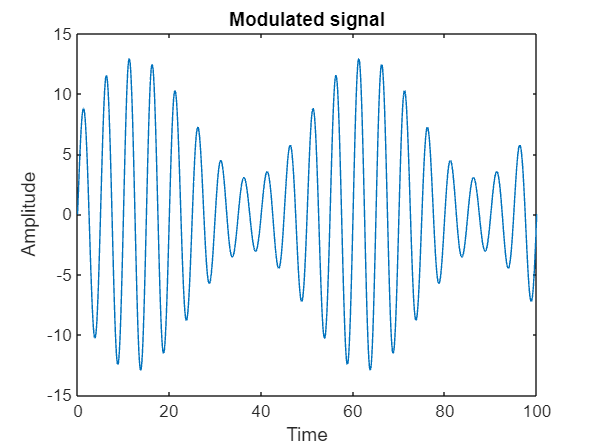

% Generating the modulated signal
s1 = (Ac + x1) .* sin(2*pi*fc*t);
plot(t,s1);
xlabel('Time');
ylabel('Amplitude');
title('Modulated signal');